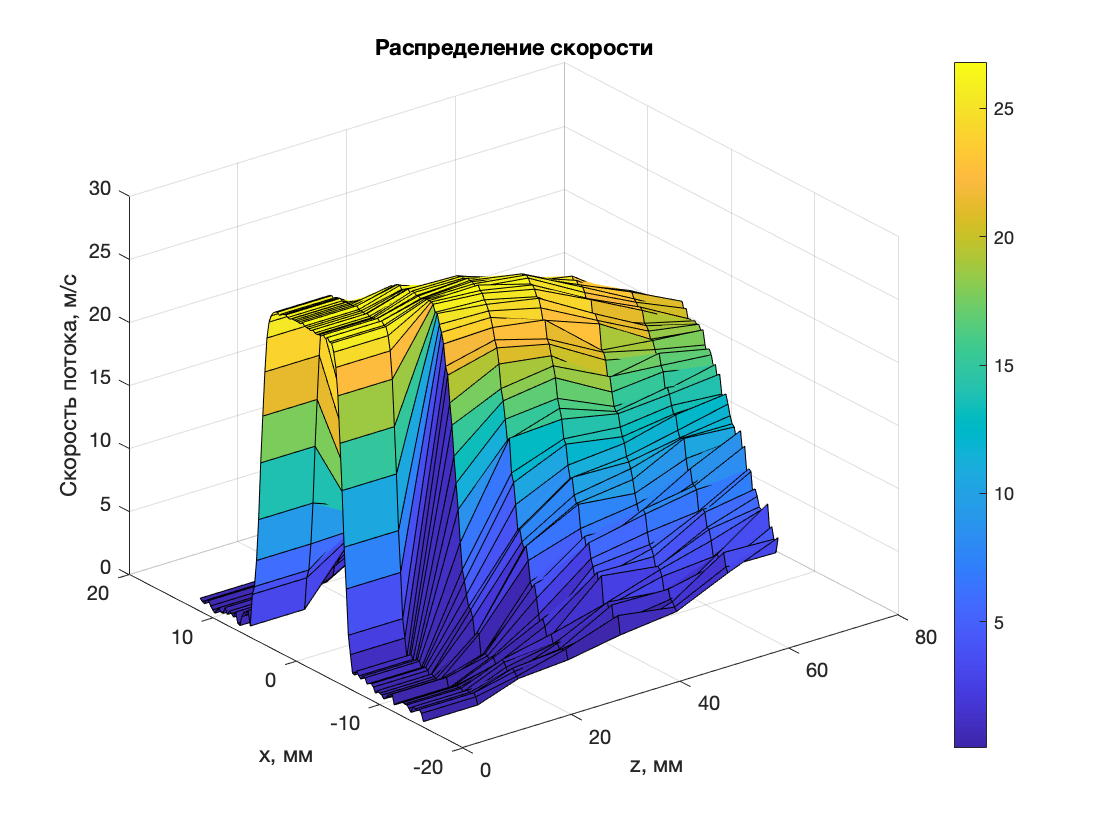

mm01 = load('01mm.dat');
mm11 = load('11mm.dat');
mm21 = load('21mm.dat');
mm31 = load('31mm.dat');
mm41 = load('41mm.dat');
mm51 = load('51mm.dat');
mm61 = load('61mm.dat');
mm71 = load('71mm.dat');

calibzero0 = load('calibzero.dat');
calib0 = load('calib.dat');

calibzero = (calibzero0(:,2))';
calib = (calib0(:,2))';
no_null = ones(size(calib)).*67.1;
null = zeros(size(calibzero));
temp_1 = [calibzero calib];
temp_2 = [null no_null];
t = polyfit(temp_1, temp_2, 1);
dx = 0.25;
x = mm01(:,1)'.*dx;

p01 = polyval(t, mm11(:, 2)');
p11 = polyval(t, mm11(:, 2)');
p21 = polyval(t, mm21(:, 2)');
p31 = polyval(t, mm31(:, 2)');
p41 = polyval(t, mm41(:, 2)');
p51 = polyval(t, mm51(:, 2)');
p61 = polyval(t, mm61(:, 2)');
p71 = polyval(t, mm71(:, 2)');

pressure = [p01; p11; p21; p31; p41; p51; p61; p71];
Names = {'1 мм', '11 мм', '21 мм', '31 мм', '41 мм', '51 мм', '61 мм', '71 мм'};
s = 1.2;
sum = 0;
for i = 1:length(calibzero)
    sum = sum + calibzero(i);
end
sum = sum/length(calibzero);
Pst = polyval(t, sum);
P0 = polyval(t, calib);

v01 = sqrt(2*abs(p01 - Pst)/s);
v11 = sqrt(2*abs(p11 - Pst)/s);
v21 = sqrt(2*abs(p21 - Pst)/s);
v31 = sqrt(2*abs(p31 - Pst)/s);
v41 = sqrt(2*abs(p41 - Pst)/s);
v51 = sqrt(2*abs(p51 - Pst)/s);
v61 = sqrt(2*abs(p61 - Pst)/s);
v71 = sqrt(2*abs(p71 - Pst)/s);

v = [v01; v11; v21; v31; v41; v51; v61; v71];

xvCentered = zeros(size(v));
offset = 12;

for i = 1:size(v,1)
    max = x(find(v(i,:) > offset, 1, "last"));
    min = x(find(v(i,:) > offset, 1, 'first'));
    center = min + (max - min)/2;
    xvCentered(i,:) = x - center;
end

f = figure;
figure(f);

plot3(10,10,10);

hold on;
grid on;

z = ones(size(pressure));

for i = 1:8
    z(i,:) = z(i,:)*((i - 1)*10 + 1);
end

surf(z, xvCentered, v);
title('Распределение скорости');
colorbar;

xlabel('z, мм');
zlabel('Скорость потока, м/с');
ylabel('x, мм');

saveas(f, 'v_distribution.png');

clear all;